# Pandulum-Cart System

A mass mp (that will be refered to as m) is attached to a car of mass mc (M) through a massless jonction with a length L (l). The car displacement is induced by a force u.  

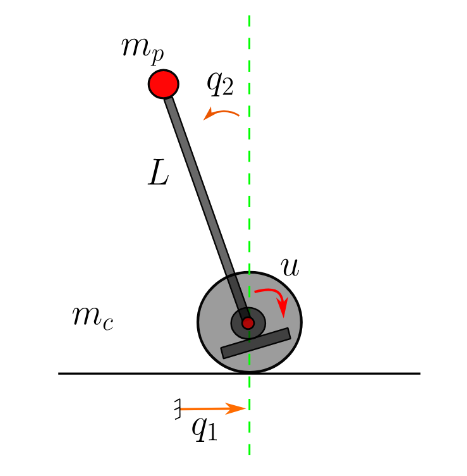

The goal of the system is to stabilize the mass mp vertically, keeping the swing angle q2 = 0 by controling the displacement q1 of the car. 

This exercice will cover the following points:

- Modeling the system using Lagrangian formalism

- Linearizing the model arround a fonctionning point of q2=0, to obtain a linear state space model

- Build a Simulink model of the system (linear and non linear model).

- Design a state feedback controller to stabilize the system

- Design a optimal controller 

- Design a mpc controller

### 1. Model of the system

The system has 2 degrees of freedom q1 and q2. 

Considering the (x,y) frame the position of the masses are given as 


$$\left\lbrace \begin{array}{ll}
\vec{\textrm{OM}\;}  & =q_1 \vec{\;x} \\
\vec{\;\textrm{Om}}  & =\left(q_1 -l\;\sin \left(q_2 \right)\right)\;\vec{x} +l\;\cos \left(q_2 \right)\;\vec{\;y} 
\end{array}\right.$$


The velocities are:


$$\left\lbrace \begin{array}{ll}
\frac{d\vec{\;\mathrm{OM}} }{\mathrm{dt}} & =\dot{\;q_1 } \;\vec{\;x} \\
\frac{d\;\vec{\;\mathrm{Om}} }{\mathrm{dt}} & =\left(\dot{\;q_1 } +l\dot{\;q_2 } \;\cos \left(q_2 \right)\right)\vec{\;x} -l{\dot{\;q} }_2 \sin \left(q_2 \right)\;\vec{\;y} 
\end{array}\right.$$


The cinetic energy of the system is given as 


$$\begin{array}{l}
T=\frac{1}{2}M\times v_M^2 +\frac{\;1}{2}m\times v_{m\;}^2 =\frac{\;1}{2}M{\dot{\;q_1 } }^2 +\frac{1}{2}{m\left(\left(\dot{\;q_1 } +l\dot{\;q_2 } \;\cos \left(q_2 \right)\right)\vec{\;x} -l{\dot{\;q} }_2 \sin \left(q_2 \right)\;\vec{\;y} \right)}^2 \\
T=\frac{1}{2}\left(M+m\right){\dot{\;q_1 } }^2 +\frac{1}{2}m\left({l^2 \dot{\;q_2 } }^2 -2l\dot{\;q_1 } \dot{\;q_2 } \cos \left(q_2 \right)\right)
\end{array}$$


The potential energy of the system is produce only by the mass m as the mass M is already grounded. So we have


$$V=\textrm{mgLcos}\left(q_2 \right)\;$$


From the about energies equation, we obtain the Lagrangian


$$L=T-V=\frac{1}{2}\left(M+m\right){\dot{\;q_1 } }^2 +\frac{1}{2}m\left({l^2 \dot{\;q_2 } }^2 -2l\dot{\;q_1 } \dot{\;q_2 } \cos \left(q_2 \right)\right)-\textrm{mgLcos}\left(q_2 \right)\;\;$$


As the system is not only conservative. It also have dissipative force (friction), generalized Lagrange equations apply as follows: 


$$\frac{d}{\mathrm{dt}}\left(\frac{\partial \;L}{\partial \;\dot{\;q_i } }\right)-\frac{\partial \;L}{\partial \;q_i }=Q_i$$


Rayleigh dissipative function will be used to introduce the friction force proportionnal to velocity. 


$$R\left(\dot{\;q} \right)=\frac{1}{2}\sum_i^N k_i {\;\dot{\;q_i } }^2 =\frac{1}{2}\;\left(k_1 {\dot{\;q_1 } }^2 +k_2 \;{\dot{\;q_2 } }^2 \right)$$


the dissipative force is given as $F_i =-\frac{\partial R}{\partial \dot{\;q_i } }\;\;\;;F_1 =-\frac{\partial R}{\partial \dot{\;q_1 } }=-\frac{1}{2}*\left({2*k}_1 \;\dot{\;q_1 } \right)=-k_1 \;\dot{q_1 }$

Thus $Q_i \;=F_i +<\textrm{other}\;\textrm{external}\;\textrm{forces}\;\textrm{applied}\;\textrm{to}\;\textrm{particle}\;i>$

- Lagrange equation w.r.t. $q_1$


$$\frac{d}{\mathrm{dt}}\left(\frac{\partial \;L}{\partial \;\dot{\;q_1 } }\right)-\frac{\partial \;L}{\partial \;q_1 }=-k_1 \;\dot{\;q_1 }$$


$\frac{\partial \;L}{\partial \;\dot{\;q_1 } }=\left(M+m\right)\dot{\;q_1 } -m\;l\;\dot{q_2 } \;\cos \left(q_2 \right)\;$;   


$$\frac{d}{\mathrm{dt}}\left(\frac{\partial \;L}{\partial \;\dot{\;q_1 } }\right)=\left(M+m\right)\ddot{\;q_1 } -m\;l\ddot{\;q_2 } \;\cos \left(q_2 \right)+m\;l\;{\dot{q_2 } }^2 \;\sin \left(q_2 \right)$$



$$\frac{\partial \;L}{\partial \;q_1 }=0$$



$$\Rightarrow \frac{d}{\textrm{dt}}\left(\frac{\partial \;L}{\partial \;\dot{\;q_1 } }\right)-\frac{\partial \;L}{\partial \;q_1 }=-k\;\dot{\;q_1 } \;\;\Rightarrow \left(M+m\right)\ddot{\;q_1 } -m\;l\ddot{\;q_2 } \;\cos \left(q_2 \right)+m\;l\;{\dot{q_2 } }^2 \;\sin \left(q_2 \right)+k_1 \;\dot{\;q_1 } =0$$


- Lagrange equation w.r.t. $q_2$

$\frac{d}{\mathrm{dt}}\left(\frac{\partial \;L}{\partial \;\dot{\;q_2 } }\right)-\frac{\partial \;L}{\partial \;q_2 }=Q_2$  . The vitual work $\delta \;W$ is produced when there is a rotation $\delta q_2$ of the arm. So we have $\delta \;W=u\;\delta \;q_2 \;$, then $Q_2 =u\;-k_2 \;\dot{\;q_2 }$


$$\;\Rightarrow -m\;l\;\ddot{\;q_1 } \;\cos \left(q_2 \right)+m\;l^{2\;} \ddot{\;q_2 } -m\;g\;l\;\sin \left(q_2 \right)=-k_2 \;\dot{\;q_2 } +\;u\;$$


The model of the system is given as 


$$\left\lbrace \begin{array}{ll}
\;\left(M+m\right)\ddot{\;q_1 } -m\;l\ddot{\;q_2 } \;\cos \left(q_2 \right)+m\;l\;{\dot{q_2 } }^2 \;\sin \left(q_2 \right)+k_1 \;\dot{\;q_1 }  & =0\\
-m\;l\;\ddot{\;q_1 } \;\cos \left(q_2 \right)+m\;l^{2\;} \ddot{\;q_2 } -m\;g\;l\;\sin \left(q_2 \right)+k_2 \;\dot{\;q_2 } \; & =u
\end{array}\right.$$


### 2. Model linearization


$$\begin{array}{l}
q_2 \approx 0\approx \epsilon \;\\
\dot{\;q_2 \;} \approx \epsilon \;\;
\end{array}$$
 
$$\Rightarrow {\dot{q_2 } }^2 =\epsilon^2 \;\;;{\dot{q_2 } }^2 q_2 =\epsilon^3 =0$$



$$q_2 \approx 0\;\Rightarrow \left\lbrace \begin{array}{ll}
\cos \left(q_2 \right) & \approx 1\\
\sin \left(q_2 \right) & \approx q_2 
\end{array}\right.$$
           


$$\Rightarrow \left\lbrace \begin{array}{ll}
\;\left(M+m\right)\ddot{\;q_1 } -m\;l\ddot{\;q_2 } \;+k_1 \;\dot{\;q_1 }  & =0\\
-m\;l\;\ddot{\;q_1 } \;+m\;l^{2\;} \ddot{\;q_2 } -m\;g\;l\;q_2 +k_2 \;\dot{\;q_2 } \; & =u
\end{array}\right.$$
    


$$\Rightarrow \left\lbrace \begin{array}{cc}
\ddot{\;q_1 }  & =\frac{\;m\;l\;}{M+m}\ddot{\;q_2 } -\frac{k_1 }{M+m}\;\dot{\;q_1 } \;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
\ddot{\;q_2 }  & =\frac{\;1}{l}\ddot{\;q_1 } -\frac{\;k_2 }{m\;l^2 }\dot{\;q_2 } +\frac{\;g}{l}q_2 +\frac{\;1}{m\;l^2 }\;u
\end{array}\right.$$
  


$$\Rightarrow \left\lbrace \begin{array}{cc}
\ddot{\;q_1 } = & \frac{\;m\;}{M+m}\ddot{\;q_1 } \;-\frac{k_2 }{\left(M+m\right)l}\dot{\;q_2 } \;+\frac{\;m\;g}{\left(M+m\right)}q_2 \;+\frac{\;1}{\left(M+m\right)l}u-\frac{k_1 }{M+m}\dot{\;q_1 } \\
\ddot{\;q_2 } = & \frac{\;m}{M+m}\ddot{\;q_2 } \;-\frac{\;k_1 }{\left(M+m\right)l}\dot{\;q_1 } -\frac{\;k_2 }{m\;l^2 }\dot{\;q_2 } +\frac{\;g}{l}q_2 +\frac{\;1}{m\;l^2 }\;u\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}\right.$$



$$\Rightarrow \left\lbrace \begin{array}{cc}
M\ddot{\;q_1 } = & -k_1 \dot{\;q_1 } -\frac{k_2 }{l}\dot{\;q_2 } \;+m\;g\;q_2 \;+\frac{\;1}{l}u\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
M\ddot{\;q_2 } = & \;-\frac{\;k_1 }{l}\dot{\;q_1 } -\frac{\left(M+m\right)\;k_2 }{m\;l^2 }\dot{\;q_2 } +\frac{\;\left(M+m\right)g}{l}q_2 +\frac{\;\left(M+m\right)}{m\;l^2 }\;u\;
\end{array}\right.$$



$$\Rightarrow \left\lbrace \begin{array}{cc}
\ddot{\;q_1 } = & -\frac{k_1 }{M}\dot{\;q_1 } -\frac{k_2 }{M\;l\;}\dot{\;q_2 } \;+\frac{\;m\;g}{M\;}q_2 \;+\frac{\;1}{M\;l}u\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
\ddot{\;q_2 } = & \;-\frac{\;k_1 }{M\;l}\dot{\;q_1 } -\frac{\left(M+m\right)\;k_2 }{M\;m\;l^2 }\dot{\;q_2 } +\frac{\;\left(M+m\right)g}{M\;l}q_2 +\frac{\;\left(M+m\right)}{M\;m\;l^2 }\;u\;\;
\end{array}\right.$$



$$\;$$



$$\Rightarrow \left\lbrace \begin{array}{ll}
\dot{\;q_1 }  & =\dot{\;q_1 } \\
\dot{\;q_2 }  & =\dot{\;q_2 } \\
\ddot{\;q_1 }  & =-\frac{k_1 }{M}\dot{\;q_1 } -\frac{k_2 }{M\;l}\dot{\;q_2 } \;+\frac{\;m\;g}{M\;l}q_2 \;+\frac{\;1}{M\;l}u\\
\ddot{\;q_2 }  & =\;-\frac{\;k_1 }{M\;l}\dot{\;q_1 } -\frac{\left(M+m\right)\;k_2 }{M\;m\;l^2 }\dot{\;q_2 } +\frac{\;\left(M+m\right)g}{M\;l}q_2 +\frac{\;\left(M+m\right)}{M\;m\;l^2 }\;u\;\;\;\;\;
\end{array}\;\right.$$
    


$$\left\lbrack \begin{array}{c}
\dot{\;q_1 } \\
\dot{\;q_2 } \\
\ddot{\;q_1 } \\
\ddot{\;q_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & \frac{\;m\;g}{M\;} & -\frac{\;k_1 }{M} & -\frac{\;k_2 }{M\;l}\\
0 & \frac{\;\left(M+m\right)g}{M\;l} & -\frac{\;k_1 }{M\;l} & -\frac{\left(M+m\right)\;k_2 }{M\;m\;l^2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
\dot{\;q_1 } \\
\dot{\;q_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
\frac{\;1}{M\;l}\\
\frac{\;\left(M+m\right)}{M\;m\;l^2 }
\end{array}\right\rbrack u$$


### 3. Simulink Model of the system

The following values will taken for the system parameters

$M=1\ldotp 5\;\textrm{kg}\;,m=0\ldotp 5\;\textrm{kg},\;g=9\ldotp 81\;m/s\;,\;l=1\;m,{\;k}_1 =k_2 =0\ldotp 01$, 

We will take $q_2 =y$ as the output of the system

clear all


run("parameters.m");

[plant_ss, plant_tf, plant_zpk] = syst_repr_generator(params, 'q2');
plant_ss.StateName = {'q_1', 'q_2', '\dot{q_1}', '\dot{q_2}'}; 
q20 = 10;
Tsim = 10;
plant_ss


plant_ss =
 
  A = 
                    q_1        q_2  \dot{q_1}  \dot{q_2}
   q_1                0          0          1          0
   q_2                0          0          0          1
   \dot{q_1}          0      3.273  -0.006667  -0.006667
   \dot{q_2}          0      13.09  -0.006667   -0.02667
 
  B = 
                  u1
   q_1             0
   q_2             0
   \dot{q_1}  0.6667
   \dot{q_2}   2.667
 
  C = 
             q_1        q_2  \dot{q_1}  \dot{q_2}
   y1          0          1          0          0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


plant_tf

plant_tf =          0         0    2.6667    0.0133   -0.0000


plant_zpk


plant_zpk =
 
        2.6667 (s+0.005)
  -----------------------------
  (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.
Model Properties


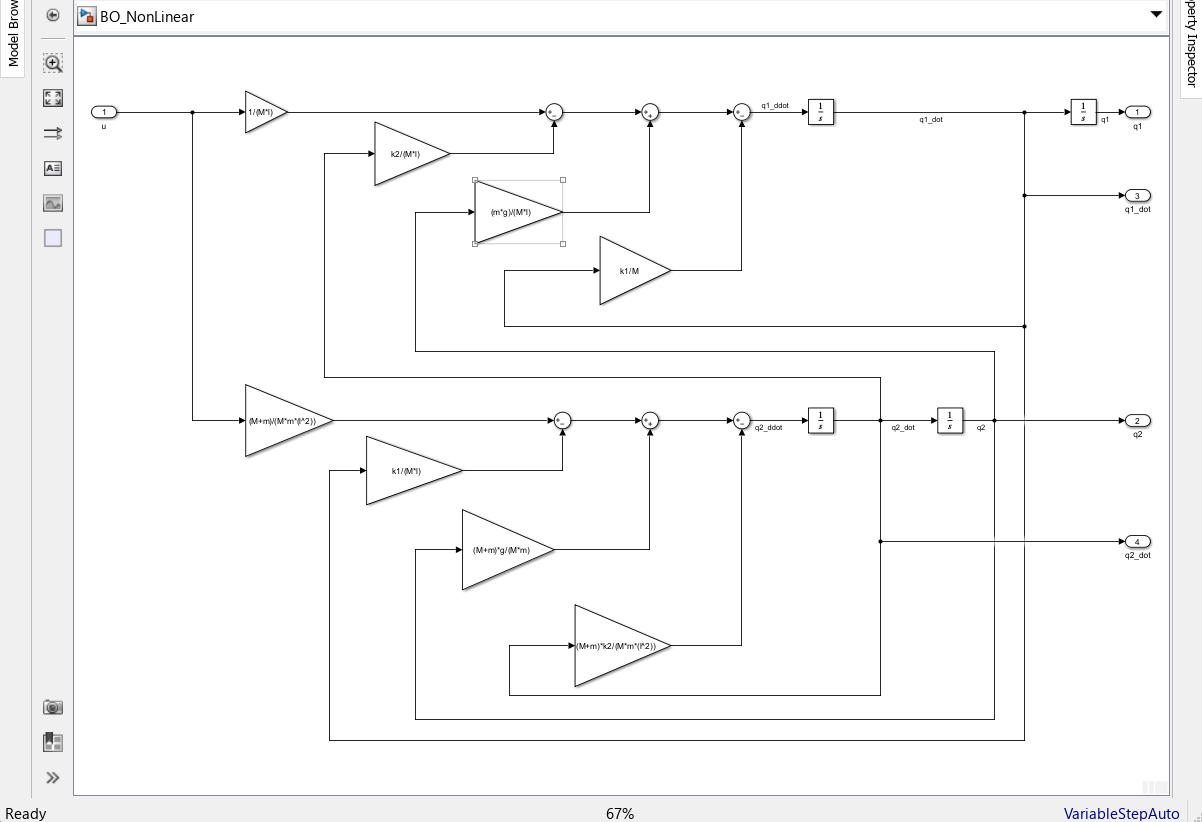

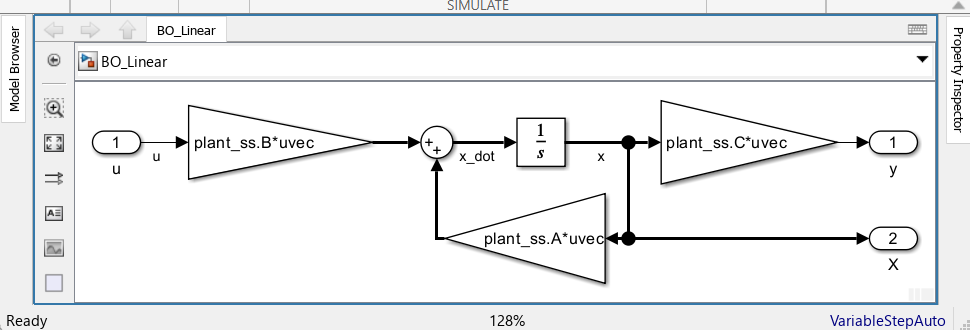

### 4. System analysis

#### Stability

poles_syst = pole(plant_ss)

poles_syst =    -3.6308
    3.6025
   -0.0050
         0


zeros_syst = zero(plant_ss)

zeros_syst =    -0.0050
         0


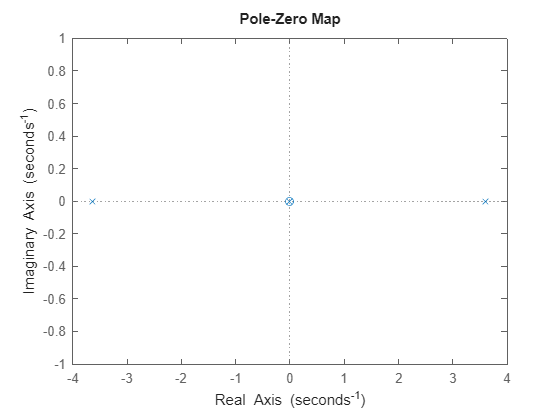

pzmap(plant_ss)

The system is unstable because the second pole of the system is a real positive.

The only one zero of the system is negative making the system minimum phase.

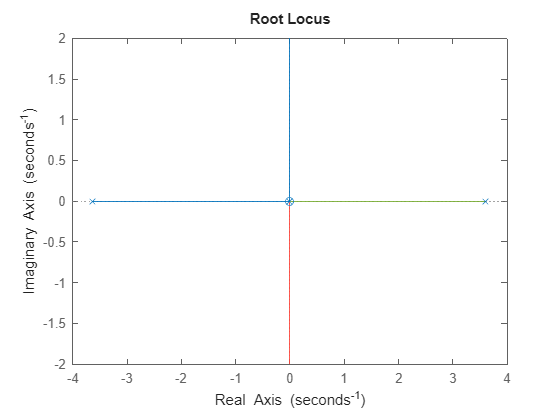


rlocus(plant_ss)


$$O\;L\;\left(s\right)=\frac{N}{D}\;\;\;;P\;\mathrm{ctrl}\;;\Rightarrow C\;L\;\left(s\right)=\frac{P\;N}{D+P\;N\;\;}$$


From the root locus we can conclude that a finite P controller only cannot stabilize the system. In fact, the system has 3 poles and 1 zero, so only one pole is pulled toward the zero as gain increases toward infinity. Event the fact that the two stable pole deverge on imaginary axis, their centroid point is in left half plan, keeping them stable. However the unstable pole approaches the zero position in the left half plan only when P is infinitly high. So no finite P controller can stabilize the system. 

Thus a solution of control is to design a controller that take into account integrator, derivator and proportional effects through loop shaping. 

s = zpk('s');
OL = (s + 1)/ (s + 3)


OL =
 
  (s+1)
  -----
  (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


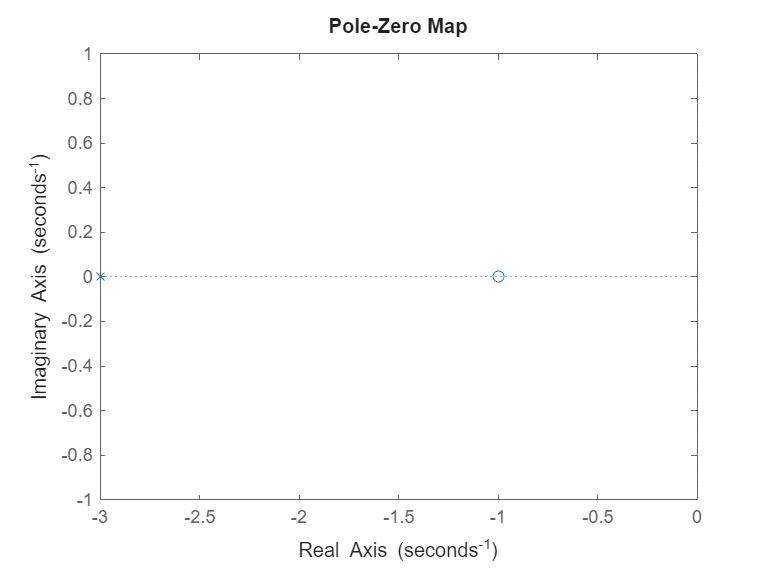

figure
pzmap(OL)

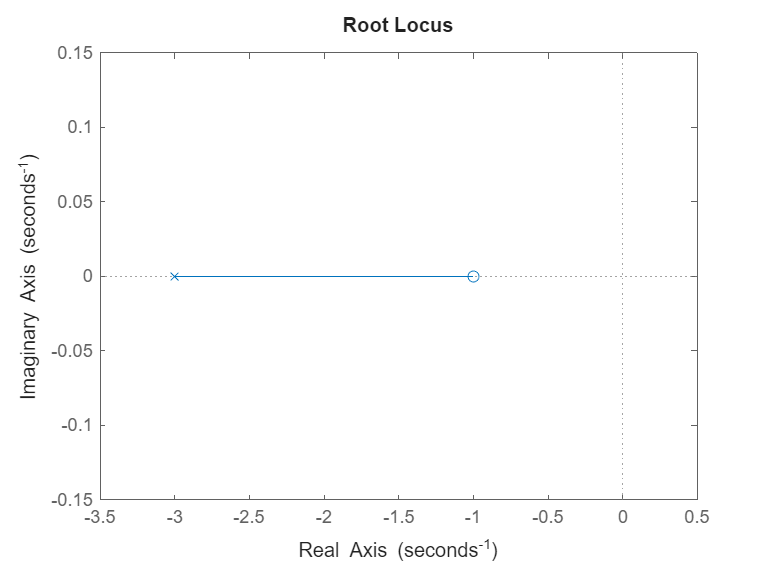

figure
rlocus(OL)

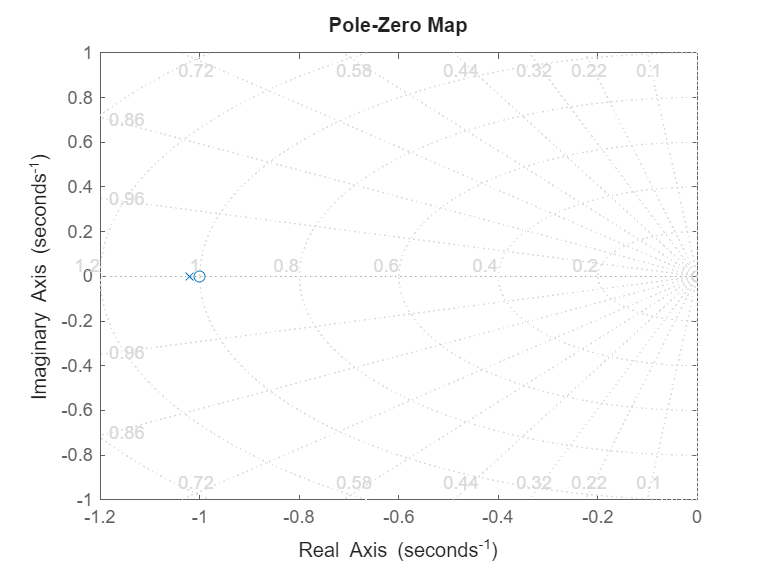


CL  = feedback(100*OL, 1);
pzmap(CL); grid on

#### Loop shaping

In this section simulink Control System Designer tool is used to tune a PID controller that stabilize the pendulum. 

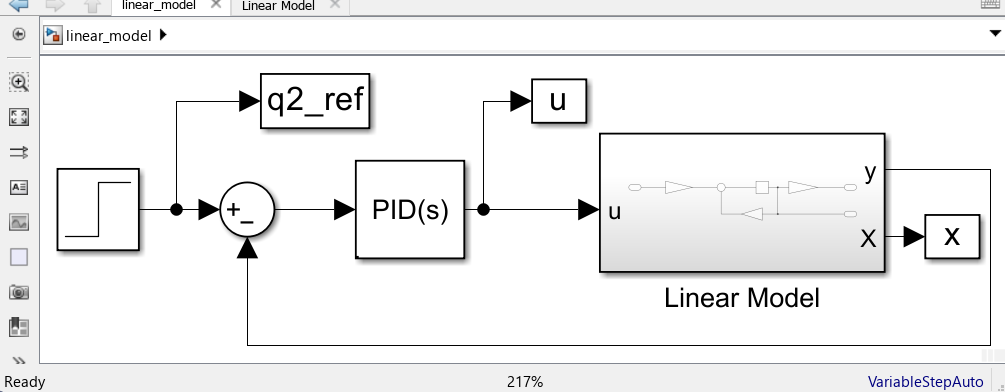

For the simulation $q_{20} =10\degree$

Tsim = 10;
q20 = 10; 
sim("CL_linear_mdl_with_PID.slx");

% animate_pendulum_cart(x.Time, x.Data(:,1), x.Data(:,2), params, 'fps', 100)


#### State feedback control

[plant_q1, plant_tf, plant_zpk] = syst_repr_generator(params,'q1');
Qc = ctrb(plant_q1);
Qo = obsv(plant_q1);
rc = rank(Qc)

rc = 3

ro = rank(Qo)

ro = 4

The system is not commandable as the rank of the commandability matrix is different from the dimension of the A. 

$r_o =3\not= \dim \left(A\right)=4$, the system is not observable.  

As the system is not commandable, there is no pur state feedback gain that can move the poles of the système to a desired place. 

So an alternative is to augment the state feedback control with integrale action. 